# **EV / EVSE **–** Charge Cycle Progression**

This example shows you how to configure the Speedgoat EV and/or EVSE CCS Charging Interface, run through a charge cycle, and read back status information.

To start a charge cycle and progress through the different charging states, the EV CCS Charging Interface's Control Pilot (CP) port will need to be connected to an EVSE station or a Speedgoat EVSE CCS Charging Interface.

Conversely, the EVSE CCS Charging Interface's Control Pilot (CP) port will need to be connected to an EV charge controller or a Speedgoat EV CCS Charging Interface.

Either one of the two module variants can be replaced with a device under test that offers an ISO 15118-2 or DIN 70121-compliant Control Pilot signal.

The Simulink model features the [EV EVSE](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_ev_evse), [EV Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_ev_status), and [EVSE Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_evse_status) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with a free Ethernet port

- Speedgoat EV CCS Charging Interface and/or Speedgoat EVSE CCS Charging Interface

- Ethernet cable

### Test Setup

In this example, a Speedgoat EV CCS Charging Interface is connected to a Speedgoat EVSE CCS Charging Interface by connecting the CP pins of both boards together; however, either one of the two modules can be replaced with a device under test offering an ISO 15118-2- or DIN 70121-compliant Control Pilot signal. If one of the devices is replaced, the respective subsystem in the Simulink model must be commented out before running the model.

If both devices are available, make sure that they are assigned unique IP addresses. New EV and EVSE CCS Charging Interfaces are both shipped with the default IP address 169.254.12.53.

### Configuration

The Speedgoat real-time target machine communicates with the Speedgoat EV and EVSE CCS Charging Interfaces over Ethernet using the MQTT protocol. For this purpose, the Ethernet port of the target machine must be configured for IP communication and assigned a suitable IP address.

In this example, the IP address assigned to the real-time target machine's Ethernet port is 169.254.12.50. If both EV and EVSE CCS are used, the two IP addresses 169.254.12.50 and 169.254.13.50 shall be assigned to two of the target machine's Ethernet ports. To set the IP address of the target machine, use the Speedgoat Ethernet Configuration tool.

 
speedgoat.configureEthernet;

If a different IP address than 169.254.12.50 is used, update the parameter "Local IP Address" in the EV EVSE block accordingly.

### Product Example Operation Modes

#### 1) EVSE CCS connected to third-party device

Comment out the "EV" subsystem in the Simulink model.

#### 2) EV CCS connected to third-party device

Comment out the "EVSE" subsystem in the Simulink model.

#### 3) EVSE CCS connected to EV CCS

The two devices need to be connected to two different Ethernet ports of the real-time target machine.

To configure the IP addresses, first only connect the EV CCS charging interface to the real-time target machine.

In the Simulink model, open the EV subsystem and double-click the EV block to open the block mask.

Click the "Ping Board" button to verify that the connection can be established. If an error shows up, use the "Ethernet Configuration" button and assign IP address 169.254.12.50 to the target machine Ethernet port that connects to the EV board.

Click the "Change IP" button; this is needed so the EV board's IP address is different from the EVSE board. Assign IP address 169.254.13.53 to the EV board. Once completed, open the "Ethernet Configuration" again and set the target machine Ethernet port to 169.254.13.50. Put the same IP address in the "Local IP Address" field of the EV block mask, then click OK. Reboot the EV board to apply the new IP address.

Now proceed to connect the EVSE CCS to the second Ethernet port of the real-time target machine, and use the Ethernet Configuration tool to ensure this port is set to IP address 169.254.12.50.

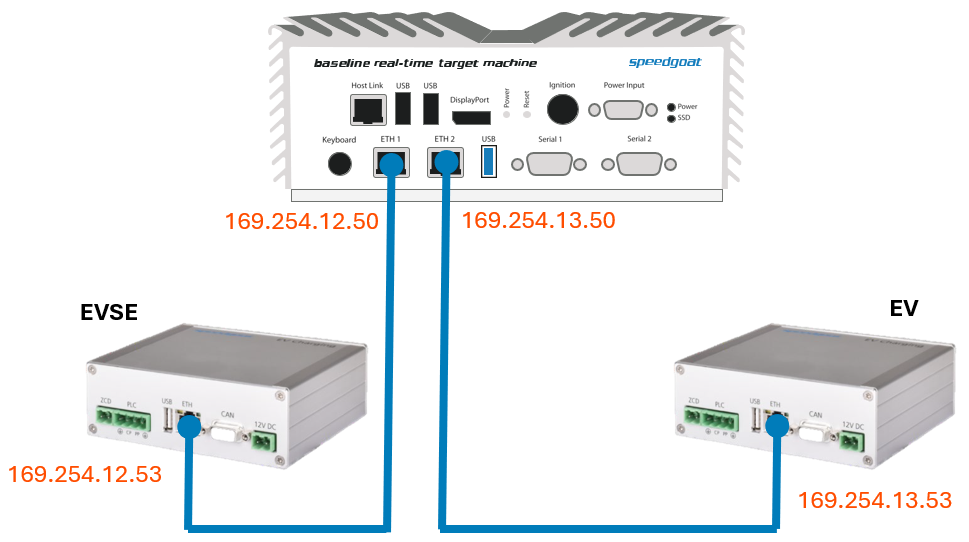

## Open Simulink Model

 
modelName = 'sgMdl_EVSE_ChargeCycleProgression';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.setStopTime(60);
tg.start;

% The real-time application on the target machine will automatically stop after 60 seconds

### Check the Results

By clicking on the scopes in the respective EV or EVSE subsystem after the model has terminated, you should be able to see the how the charging state progressed over time.

In the following screenshot, the Control Pilot (CP) pins were connected at roughly t=10 s, at which point the charging state goes to 1 = "Initialization". The following charging states are handled automatically using the input charging parameters from the Simulink model until charging state 6 = "Charging" is reached.

At roughly t=46 s, the EV parameter "Ready to Charge State" is set to "Stop" ('1'), causing the charge cycle to go to state 7 = "Welding", after which the charge cycle is terminated.

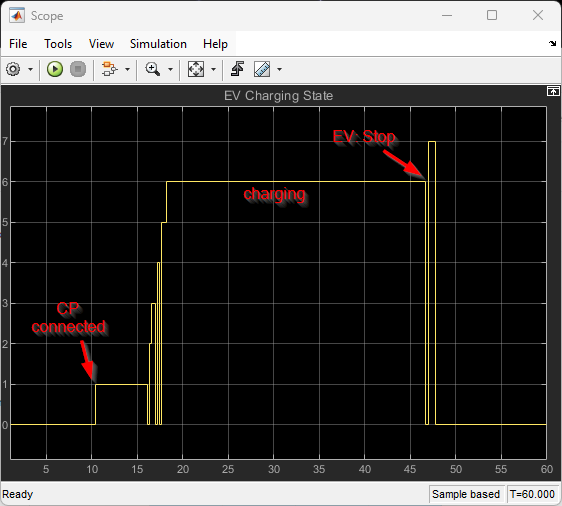

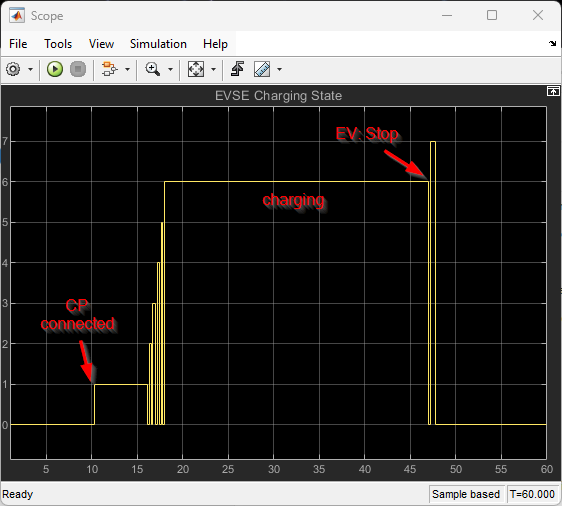

Note that the intermediate dips of the charging state status signal to '0' are due to the way the state is received using the MQTT protocol. There is usually a short time interval where one charging state reports "finished" while the next state has not yet changed to "started". This results in an output of '0' for the charging state output of the [EV Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_ev_status) and [EVSE Status](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_evse_status) blocks.

## Additional References

- [EV Charging Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_evcharging_usage_notes)